# Train Voxel Classifier

## Getting a First Impression about the Data

### Load one of the data sets into memory

% Point to data folder
data_root = "/Users/amithkamath/data/MSD/Task04_Hippocampus";

%Alternative: Select one of the folders using a slider...

image_folder = data_root + filesep + "imagesTr";
label_folder = data_root + filesep + "labelsTr";
image_hip = niftiread(image_folder + filesep + "hippocampus_001.nii.gz");
label_hip = categorical(niftiread(label_folder + filesep + "hippocampus_001.nii.gz"));

Note that the individual data files can have different datatypes!

### Visualize Slices of the Data Set

n_height = size(image_hip,3);
slice=10;
figure("Position",[0 0 1000 800])
tiledlayout(2,2)
nexttile
imagesc(image_hip(:,:,slice),[min(image_hip,[],"all") max(image_hip,[],"all")])
title("MR image")
nexttile
imagesc(double(label_hip(:,:,slice)),[0 2])
title("label")

### Visualize the complete volume

viewer = viewer3d(); %this is helpful if we would like to show more than just one volume
masked_hip=uint8(uint8(label_hip) == 2).*image_hip; %better to use the mask here
volshow(masked_hip, Parent=viewer); %display the volume in the selected viewer

## Batch preprocessing of training and test data

This processes the data in every sample folder and adds it to a feature table. The process of this preprocessing is described in detail in [Preprocessing.mlx](matlab:open('./Preprocessing.mlx'))

image_files = dir(image_folder);
label_files = dir(label_folder);

images_train = image_files(1:180,:);
labels_train = label_files(1:180,:);

images_test = image_files(181:end,:);
labels_test = label_files(181:end,:);

train_dataset=table;
% the 4 below is hard coded. would be a good to adapt this automatically to
% the output of the dir function.
for n = 3:10 %length(images_train)
    image_path=string(images_train(n).folder) + filesep + string(images_train(n).name)
    label_path=string(labels_train(n).folder) + filesep + string(labels_train(n).name)
    try
        tab = preprocess_msdhip(image_path, label_path);
        train_dataset=[train_dataset; tab];
    catch error
        fprintf("Errored. Skipping volume.");
    end
end

## Balancing of Data Sets

Before we train a Machine Learning algorithm, it is best practice to check the number of labels in the individual classes.

PS: Note that we have removed the masked voxels (class=0).

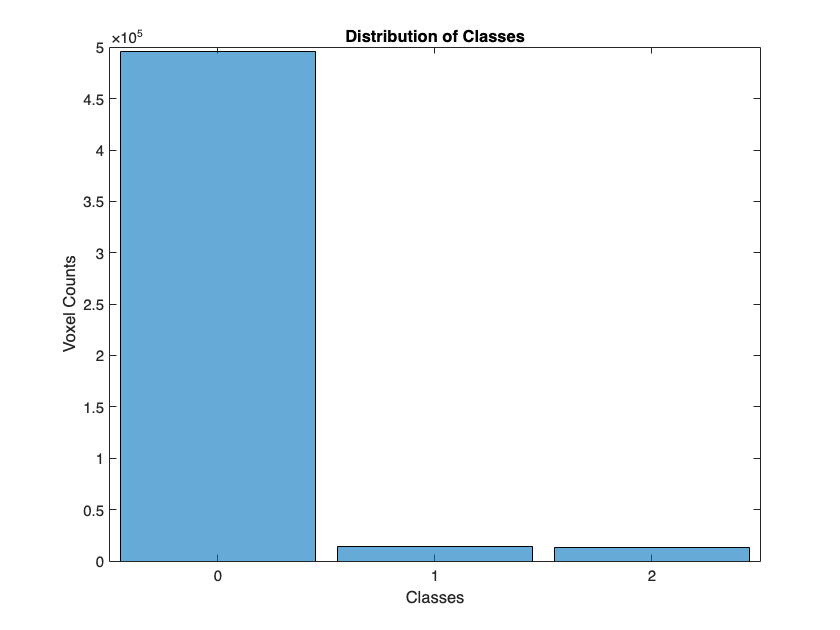

figure
histogram(train_dataset.label)
title("Distribution of Classes")
ylabel("Voxel Counts")
xlabel("Classes")

If the distribution of the classes is unbalanced this might lead to a biased prediction. This however depends on the specific algorithm. Some of them are less prone to unbalanced datasets than others.

Because we have a lot of voxels, we can afford to drop some of the observations. We thus balance the dataset by undersampling overrepresented classes. 

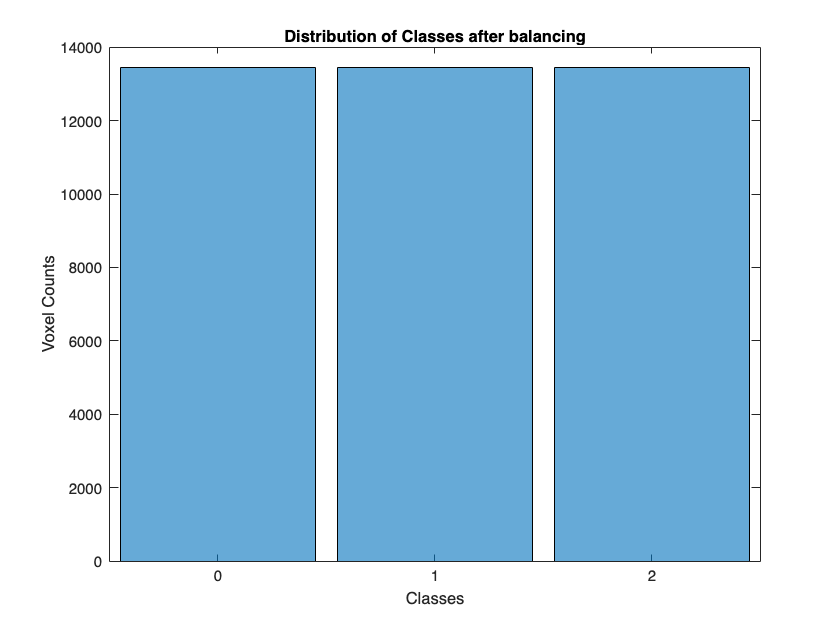

tab_train=balanceTable(train_dataset);
tab_test=balanceTable(test_dataset);

figure
histogram(tab_train.label)
title("Distribution of Classes after balancing")
ylabel("Voxel Counts")
xlabel("Classes")

## Training of a Classifier

open the classification learner:

classificationLearner

- start a new session from workspace

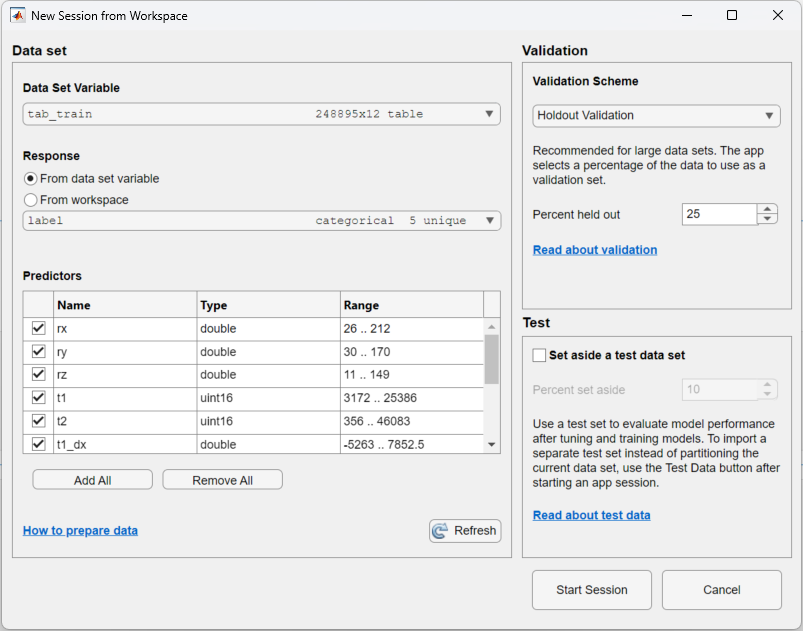

- Select models to train and click "Train all"

- Evaluate the Confusion Matrix

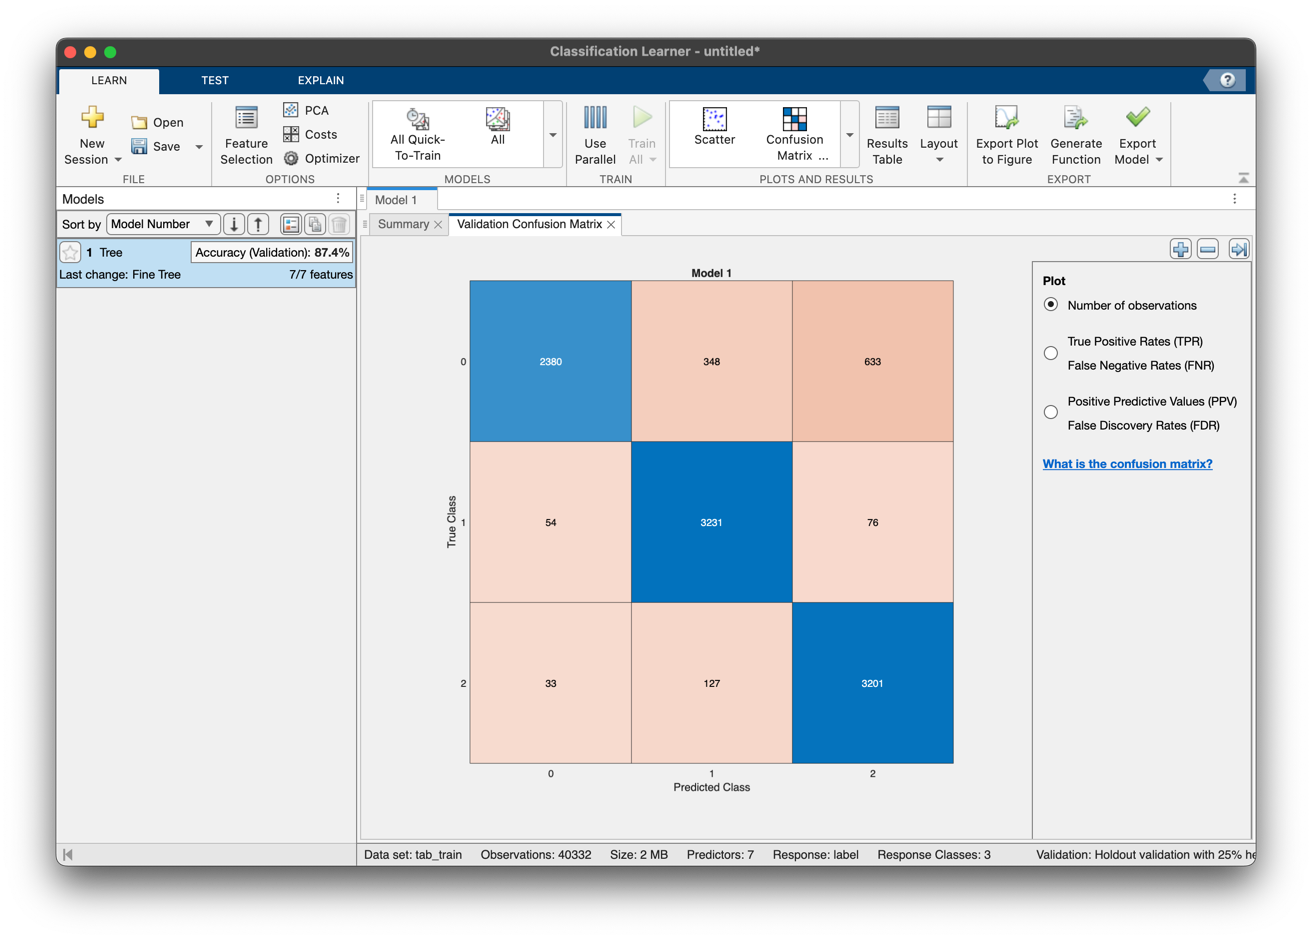

- Export the model

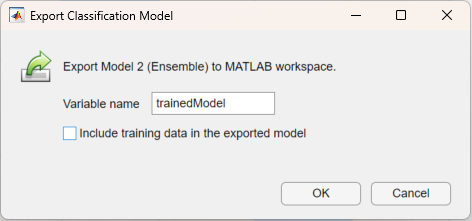

%train and test models using classification learner
%first try -> 87.4% test accuracy


## Apply this to a Specimen

test_dataset=table;
for n=3:5 %length(folder_test)
    image_path=string(images_test(n).folder) + filesep + string(images_test(n).name)
    label_path=string(labels_test(n).folder) + filesep + string(labels_test(n).name)
    try
        tab = preprocess_msdhip(image_path, label_path);
        [yfit, scores] = trainedModel.predictFcn(tab(:, 1:7));

        image_data = niftiread(image_path);
        label_reshaped = reshape(yfit, size(image_data));

        label_data = categorical(niftiread(label_path));
        dsc = dice(label_reshaped, label_data);
        fprintf("Mean Dice score for subject %d is %f\n", n, mean(dsc));
    catch
        fprintf("Errored. Skipping volume.");
    end
end

image_path = "/Users/amithkamath/data/MSD/Task04_Hippocampus/imagesTr/hippocampus_287.nii.gz"

label_path = "/Users/amithkamath/data/MSD/Task04_Hippocampus/labelsTr/hippocampus_287.nii.gz"

Mean Dice score for subject 3 is 0.470166


image_path = "/Users/amithkamath/data/MSD/Task04_Hippocampus/imagesTr/hippocampus_288.nii.gz"

label_path = "/Users/amithkamath/data/MSD/Task04_Hippocampus/labelsTr/hippocampus_288.nii.gz"

Mean Dice score for subject 4 is 0.474198


image_path = "/Users/amithkamath/data/MSD/Task04_Hippocampus/imagesTr/hippocampus_289.nii.gz"

label_path = "/Users/amithkamath/data/MSD/Task04_Hippocampus/labelsTr/hippocampus_289.nii.gz"

Mean Dice score for subject 5 is 0.420371


volumeViewer
%inspect volume labels by importing labeled volume from workspace

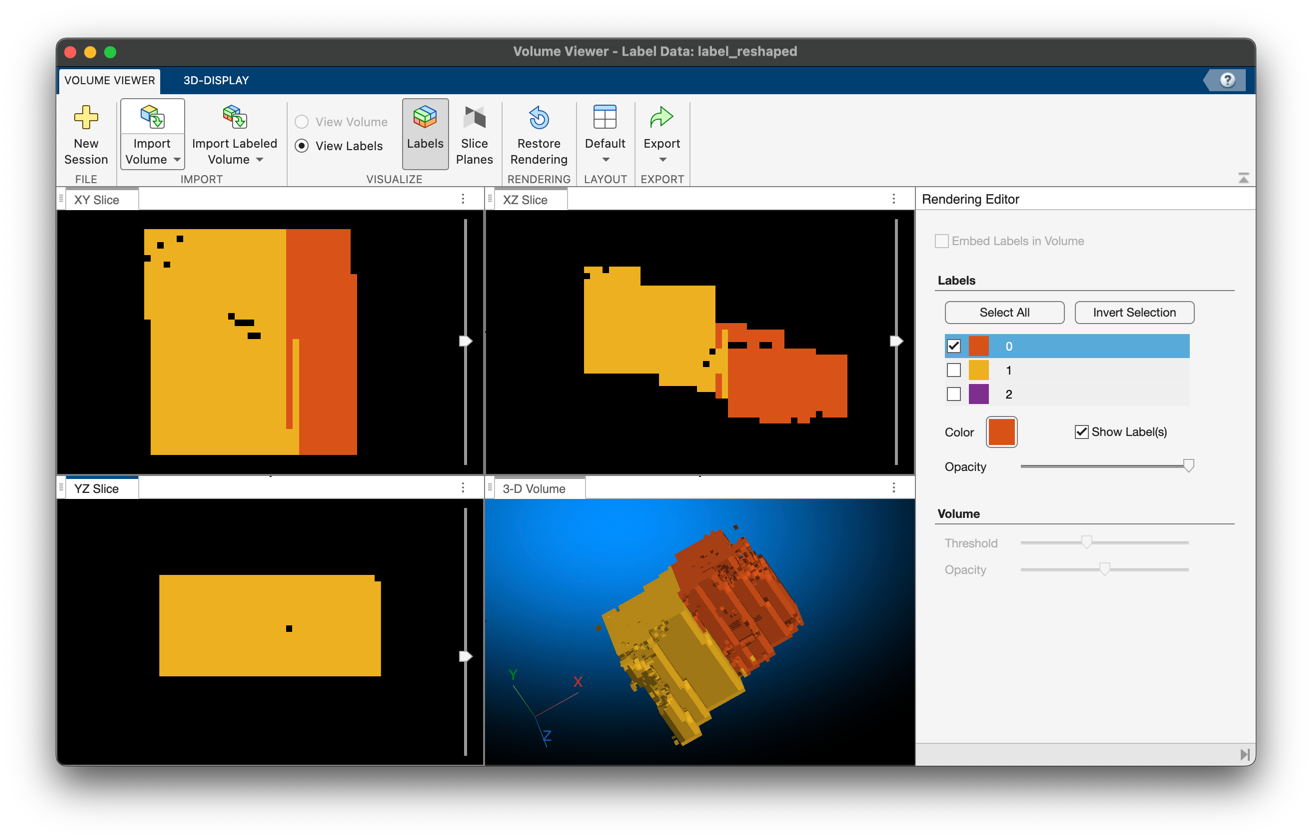

function tab_data=balanceTable(dataset)

    [Values,Categories]=histcounts(dataset.label);
    
    ind=Values==0;
    Values(ind)=[];
    Categories=Categories(~ind);
    % use the class with the lowest number of voxels as a the threshold for
    % the other classes.
    threshold=min(Values);
        
    tab_data=table;
    for n=1:length(Values)
        subset=randperm(Values(n),threshold);
        tab_class=dataset(dataset.label==Categories{n},:);
        tab_data=[tab_data; tab_class(subset,:)];
    end

end